clear, clc
close all

datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_BANDA_s6.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;

FC_run1 = atanh(FC_run1);
FC_run1(FC_run1==0) = NaN;
FC_run1(~isfinite(FC_run1)) = NaN;
FC_run1(outlier_run1,:) = NaN; % num of spikes > num of timepoints * 0.25

FC_run2 = atanh(FC_run2);
FC_run2(FC_run2==0) = NaN;
FC_run2(~isfinite(FC_run2)) = NaN;
FC_run2(outlier_run2,:) = NaN; % num of spikes > num of timepoints * 0.25

FC = [];
FC(:, :, 1) = FC_run1;
FC(:, :, 2) = FC_run2;
clear FC_*
FC = mean(FC, 3, 'omitnan');
FC = FC(:, parcel_idx);

PE = [ones(206, 1) FC] * b_pls;
clear FC*
excluded_fmri = outlier_run1 & outlier_run2;

T = readtable(fullfile(datadir, 'ndar_subject01.csv'),'VariableNamingRule', 'preserve', 'TreatAsEmpty', 'n/a');
control = false(206,1);
depression = false(206,1);
anxiety = false(206,1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.visit,'T1');
    if sum(idx) == 1
    if strcmp(T.phenotype(idx),'Control')
        control(i) = true;
    elseif strcmp(T.phenotype(idx),'Depression')
        depression(i) = true;
    elseif strcmp(T.phenotype(idx),'Anxiety')
        anxiety(i) = true;
    end
    end
end

## MFQ

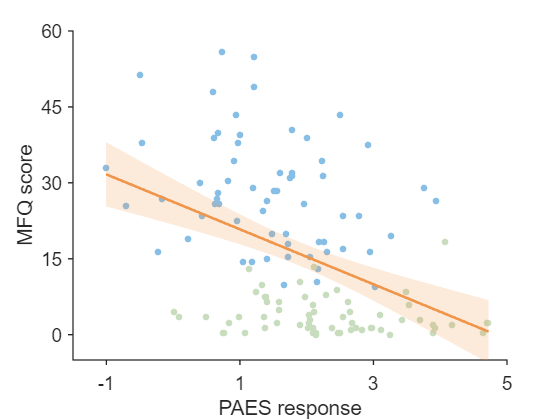

T = readtable(fullfile(datadir, 'mfq01.csv'),'FileType', "delimitedtext", "VariableNamingRule", "preserve", 'TreatAsEmpty', 'n/a');
mfq_child = nan(206, 1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.respondent,'Child') & strcmp(T.visit,'T1');
    if sum(idx) == 1
        if strcmp(T.sex(idx),'M')
            sex = 0;
        elseif strcmp(T.sex(idx),'F')
            sex = 1;
        else 
            sex = nan;
        end
%         mfq_child(i,:) = [T.mfqtot(idx), T.interview_age(idx), sex];
        mfq_child(i,:) = T.mfqtot(idx);
    end
end

mfq_parent = nan(206, 1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.respondent,'Parent')  & strcmp(T.visit,'T1');
    if sum(idx) == 1
        if strcmp(T.sex(idx),'M')
            sex = 0;
        elseif strcmp(T.sex(idx),'F')
            sex = 1;
        else 
            sex = nan;
        end
%         mfq_parent(i,:) = [T.mfqtot(idx), T.interview_age(idx), sex];
        mfq_parent(i,:) = T.mfqtot(idx);
    end
end

% PAES
mfq = [mfq_child(:,1), mfq_parent(:,1)];
mfq = mean(mfq, 2, 'omitnan');
excluded_rating = isnan(mfq);
excluded = excluded_fmri | excluded_rating;


PAES_PE_depr = PE(depression&(~excluded), 1);
MFQ_depre = mfq(depression&(~excluded));
PAES_PE_con = PE(control&(~excluded), 1);
MFQ_con = mfq(control&(~excluded));

x = [PAES_PE_depr; PAES_PE_con];
y = [MFQ_depre; MFQ_con];

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');


xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(PAES_PE_depr, MFQ_depre, 25, cols1(4,:), 'filled')  
scatter(PAES_PE_con, MFQ_con, 25, cols1(8,:),  'filled')


fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(1,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(1,:), 'LineWidth', 2);

xlabel('PAES response');
ylabel('MFQ score'); 
set(gca,'YLim', [-5 60], 'ytick',0:15:60, 'XLim', [-1.5 5], 'xtick',-1:2:5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

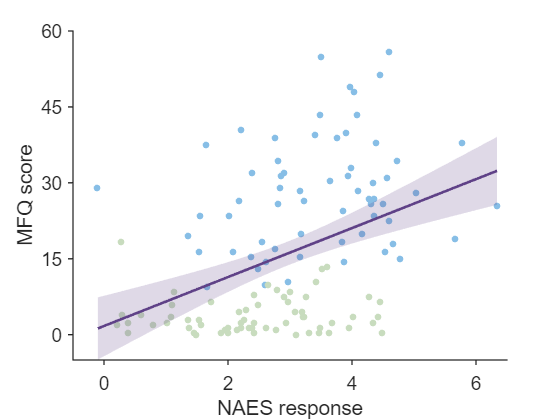

% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_BANDA_MFQ', '-r400')
% close all

% NAES
NAES_PE_depr = PE(depression&(~excluded), 2);
MFQ_depre = mfq(depression&(~excluded));
NAES_PE_con = PE(control&(~excluded), 2);
MFQ_con = mfq(control&(~excluded));

x = [NAES_PE_depr; NAES_PE_con];
y = [MFQ_depre; MFQ_con];

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');


xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(NAES_PE_depr, MFQ_depre, 25, cols1(4,:), 'filled')  
scatter(NAES_PE_con, MFQ_con, 25, cols1(8,:),  'filled')

fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(3,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(3,:), 'LineWidth', 2);

xlabel('NAES response');
ylabel('MFQ score'); 
set(gca,'YLim', [-5 60], 'ytick',0:15:60, 'XLim', [-0.5 6.5], 'xtick',0:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_BANDA_MFQ', '-r400')
% close all

## SHAPS

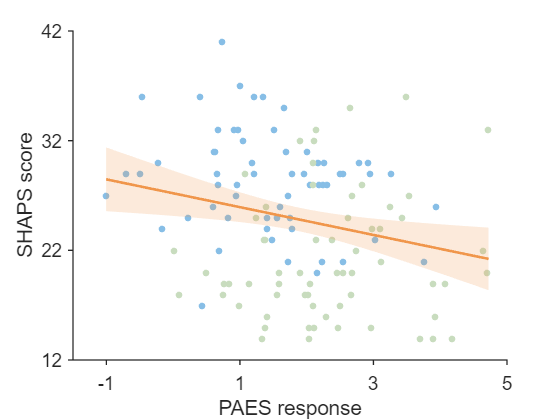

T = readtable(fullfile(datadir, 'shaps01.csv'),'FileType', "delimitedtext", "VariableNamingRule", "preserve", 'TreatAsEmpty', 'n/a');
shaps = nan(206, 5);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.respondent,'Child') & strcmp(T.visit,'T1');
    if sum(idx) == 1
        if strcmp(T.sex(idx),'M')
            sex = 0;
        elseif strcmp(T.sex(idx),'F')
            sex = 1;
        else 
            sex = nan;
        end
        shaps(i,:) = [T.shaps_total(idx), T.shaps_total_continuous(idx), T.shaps_total_dichotomous(idx), T.interview_age(idx), sex];
    end
end

excluded_rating = isnan(shaps(:,1));
excluded = excluded_fmri | excluded_rating;

% PAES
PAES_PE_depr = PE(depression&(~excluded), 1);
shaps_depre = shaps(depression&(~excluded),2);
PAES_PE_con = PE(control&(~excluded), 1);
shaps_con = shaps(control&(~excluded), 2);

x = [PAES_PE_depr; PAES_PE_con];
y = [shaps_depre; shaps_con];

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');


xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(PAES_PE_depr, shaps_depre, 25, cols1(4,:), 'filled')  
scatter(PAES_PE_con, shaps_con, 25, cols1(8,:),  'filled')


fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(1,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(1,:), 'LineWidth', 2);

xlabel('PAES response');
ylabel('SHAPS score'); 
set(gca,'YLim', [12 42], 'ytick',12:10:42, 'XLim', [-1.5 5], 'xtick',-1:2:5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

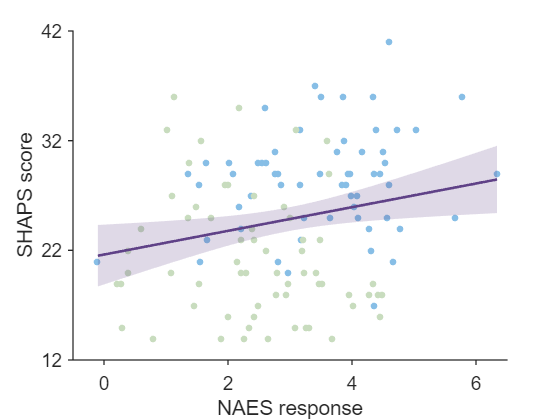

% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_BANDA_shaps', '-r400')
% close all

% NAES
NAES_PE_depr = PE(depression&(~excluded), 2);
shaps_depre = shaps(depression&(~excluded), 2);
NAES_PE_con = PE(control&(~excluded), 2);
shaps_con = shaps(control&(~excluded), 2);

x = [NAES_PE_depr; NAES_PE_con];
y = [shaps_depre; shaps_con];

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');


xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(NAES_PE_depr, shaps_depre, 25, cols1(4,:), 'filled')  
scatter(NAES_PE_con, shaps_con, 25, cols1(8,:),  'filled')


fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(3,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

plot(xg, yg, 'Color', cols(3,:), 'LineWidth', 2);

xlabel('NAES response');
ylabel('SHAPS score'); 
set(gca,'YLim', [12 42], 'ytick',12:10:42, 'XLim', [-0.5 6.5], 'xtick',0:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

% axis square
% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_BANDA_shaps', '-r400')
% close all